% L = [3.7/2 3.7/2  0.2 1.6 0.2 3.7/2 3.7/2];
% R_o = [0.3 0.3 1 0.3 1.25 0.3 0.3];

% L = [3.7/3 3.7/3 3.7/3  0.2 1.6 0.2 3.7/3 3.7/3 3.7/3];
% R_o = [0.3 0.3 0.3 1 0.3 1.25 0.3 0.3 0.3];

% L = [3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 ...
%      3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 0.2 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 0.2 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 ...
%      3.7/18 3.7/18 3.7/18 3.7/18 3.7/18 3.7/18];
% R_o = [0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 1 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 1.25 ...
%        0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3];

L = [3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 ...
     3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 0.2 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 1.6/8 0.2 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 ...
     3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19 3.7/19];
R_o = [0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 1 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 1.25 ...
       0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3 0.3];

E = 200e9;
nu = 0.3;
rho = 7850;
R_i = 0;
pi = 3.1415;
S = pi.*(R_o.^2 - R_i.^2);
I = pi.*(R_o.^4 - R_i.^4)/4; % SECOND MOMENT AREA OR MOMENT OF INERTIA OF CIRCLE
size_L = size(L);
rho = rho.*ones(size_L);
S = S.*ones(size_L);
E = E.*ones(size_L);
I = I.*ones(size_L);
n = size_L(2) + 1;  % Number Of Elements
S_r = S;
G = E./(2*(1 + nu));
a = (12*E.*I)./(G.*S_r.*L.^2);
% a = zeros(size_L);
M = zeros(n*4);
C = zeros(n*4);
K = zeros(n*4);
for k = 0:n - 2
    %     M_0 = [156    0     0      22*L(k+1)   54    0     0       -13*L(k+1);
    %        0      156   -22*L(k+1)  0      0     54    13*L(k+1)     0;
    %        0     -22*L(k+1)  4*L(k+1)^2  0      0    -13*L(k+1) -3*L(k+1)^2    0;
    %        22*L(k+1)   0     0      4*L(k+1)^2  13*L(k+1)  0     0       -3*L(k+1)^2;
    %        54     0     0      13*L(k+1)   156   0     0       -22*L(k+1);
    %        0      54    -13*L(k+1)  0      0     156   22*L(k+1)     0;
    %        0      13*L(k+1) -3*L(k+1)^2  0      0     22*L(k+1)  4*L(k+1)^2    0;
    %       -13*L(k+1)   0     0     -3*L(k+1)^2  -22*L(k+1)  0    0        4*L(k+1)^2]*rho(k+1)*S(k+1)*L(k+1)/(420);

    M_0 = [156        0          0           22*L(k+1)    54         0          0            -13*L(k+1);
           0          156       -22*L(k+1)   0            0          54         13*L(k+1)     0;
           0         -22*L(k+1)  4*L(k+1)^2  0            0         -13*L(k+1) -3*L(k+1)^2    0;
           22*L(k+1)  0          0           4*L(k+1)^2   13*L(k+1)  0          0            -3*L(k+1)^2;
           54         0          0           13*L(k+1)    156        0          0            -22*L(k+1);
           0          54        -13*L(k+1)   0            0          156        22*L(k+1)     0;
           0          13*L(k+1) -3*L(k+1)^2  0            0          22*L(k+1)  4*L(k+1)^2    0;
          -13*L(k+1)  0          0          -3*L(k+1)^2  -22*L(k+1)  0          0             4*L(k+1)^2]*rho(k+1)*S(k+1)*L(k+1)/(420*(1+a(k+1))^2);

    M_1 = [294     0      0      38.5*L(k+1)    126      0         0       -31.5*L(k+1);
        0       294    -38.5*L(k+1)  0       0        126       31.5*L(k+1)  0;
        0      -38.5*L(k+1) 7*L(k+1)^2   0        0       -31.5*L(k+1)   -7*L(k+1)^2   0;
        38.5*L(k+1)  0      0       7*L(k+1)^2    31.5*L(k+1)   0         0       -7*L(k+1)^2;
        126     0      0       31.5*L(k+1)   294      0         0       -38.5*L(k+1);
        0       126    -31.5*L(k+1) 0        0        294       38.5*L(k+1)  0;
        0       31.5*L(k+1) -7*L(k+1)^2  0        0        38.5*L(k+1)  7*L(k+1)^2   0;
        -31.5*L(k+1) 0       0      -7*L(k+1)^2   -38.5*L(k+1)  0         0       7*L(k+1)^2]*rho(k+1)*S(k+1)*L(k+1)/(420*(1+a(k+1))^2);

    M_2 = [140     0        0          17.5*L(k+1)        70      0           0            -17.5*L(k+1);
        0       140     -17.5*L(k+1)     0             0       70          17.5*L(k+1)        0;
        0      -17.5*L(k+1)   3.5*L(k+1)^2    0             0      -17.5*L(k+1)     -3.5*L(k+1)^2       0;
        17.5*L(k+1)  0        0          3.5*L(k+1)^2       15.7*L(k+1)  0           0            -3.5*L(k+1)^2;
        70      0        0          15.7*L(k+1)        140     0           0            -17.5*L(k+1);
        0       70      -17.5*L(k+1)     0             0       140        17.5*L(k+1)         0;
        0       17.5*L(k+1)  -3.5*L(k+1)^2    0             0       17.5*L(k+1)     3.5*L(k+1)^2        0;
        -17.5*L(k+1)  0        0         -3.5*L(k+1)^2      -17.5*L(k+1)  0          0              3.5*L(k+1)^2]*rho(k+1)*S(k+1)*L(k+1)/(420*(1+a(k+1))^2);
    M_ref = M_0 + a(k+1)*M_1 + a(k+1)^2*M_2;

    g1 = 36;
    g2 = (3 - 15*a(k+1))*L(k+1);
    g3 = (4+5*a(k+1)+10*a(k+1)^2)*L(k+1)^2;
    g4 = (-1 -5*a(k+1) + 5*a(k+1)^2)*L(k+1)^2;
    G = [0  -g1  g2  0   0  g1  g2  0;
        g1  0    0   g2 -g1 0   0   g2;
        -g2  0    0  -g3  g2 0   0  -g4;
        0  -g2   g3  0   0  g2  g4  0;
        0   g1  -g2  0   0 -g1 -g2  0;
        -g1  0    0  -g2  g1 0   0  -g2;
        -g2  0    0  -g4  g2 0   0  -g3;
        0  -g2   g4  0   0  g2  g3  0];
    C_ref = G*(rho(k+1)*I(k+1)/(15*L(k+1)*a(k+1)^2));

    %     K_C = [12   0    0        -6*L(k+1)      -12     0     0        -6*L(k+1);
    %            0    12   6*L(k+1)       0         0     -12    6*L(k+1)       0;
    %            0    6*L(k+1) (4+a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (2-a(k+1))*L(k+1)^2  0;
    %           -6*L(k+1)  0    0        (4+a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (2-a(k+1))*L(k+1)^2;
    %           -12   0    0         6*L(k+1)       12     0     0         6*L(k+1);
    %            0   -12  -6*L(k+1)       0         0      12   -6*L(k+1)       0;
    %            0    6*L(k+1) (2-a(k+1))*L(k+1)^2  0         0     -6*L(k+1)  (4+a(k+1))*L(k+1)^2  0;
    %           -6*L(k+1)  0    0        (2-a(k+1))*L(k+1)^2  6*L(k+1)    0     0        (4+a(k+1))*L(k+1)^2;]*E(k+1)*I(k+1)/((1+a(k+1))*L(k+1)^3);

    K_0 = [12   0    0         6*L(k+1)      -12     0     0         6*L(k+1);
        0    12  -6*L(k+1)       0         0     -12   -6*L(k+1)       0;
        0   -6*L(k+1)  4*L(k+1)^2     0         0      6*L(k+1)   2*L(k+1)^2     0;
        6*L(k+1)  0    0         4*L(k+1)^2    -6*L(k+1)    0     0         2*L(k+1)^2;
        -12   0    0        -6*L(k+1)       12     0     0        -6*L(k+1);
        0   -12   6*L(k+1)       0         0      12    6*L(k+1)       0;
        0   -6*L(k+1)  2*L(k+1)^2     0         0      6*L(k+1)   4*L(k+1)^2     0;
        6*L(k+1)  0    0         2*L(k+1)^2    -6*L(k+1)    0     0         4*L(k+1)^2;]*E(k+1)*I(k+1)/((1+a(k+1))*L(k+1)^3);

    K_1 = [0   0   0      0      0   0   0      0;
        0   0   0      0      0   0   0      0;
        0   0   L(k+1)^2    0      0   0  -L(k+1)^2    0;
        0   0   0      L(k+1)^2    0   0   0     -L(k+1)^2;
        0   0   0      0      0   0   0      0;
        0   0   0      0      0   0   0      0;
        0   0  -L(k+1)^2    0      0   0   L(k+1)^2    0;
        0   0   0     -L(k+1)^2    0   0   0      L(k+1)^2]*E(k+1)*I(k+1)/((1+a(k+1))*L(k+1)^3);
    K_C = K_0 + a(k+1)*K_1;

    %         M_s = [36   0    0     -3*L(k+1)   -36   0       0     -3*L(k+1);
    %            0    36   3*L(k+1)    0      0   -36      3*L(k+1)    0;
    %            0    3*L(k+1)  4*L(k+1)^2  0      0   -3*L(k+1)    -L(k+1)^2    0;
    %           -3*L(k+1)  0    0      4*L(k+1)^2  3*L(k+1)  0       0     -L(k+1)^2;
    %           -36   0    0      3*L(k+1)    36   0       0      3*L(k+1);
    %            0   -36  -3*L(k+1)    0      0    36     -3*L(k+1)    0;
    %            0    3*L(k+1) -L(k+1)^2    0      0   -3*L(k+1)     4*L(k+1)^2  0;
    %           -3*L(k+1)  0    0     -L(k+1)^2    3*L(k+1)  0       0      4*L(k+1)^2]*rho(k+1)*I(k+1)/(30*L(k+1));
    %         N = M_s;

    N_0 = [36   0    0      3*L(k+1)   -36   0       0      3*L(k+1);
        0    36  -3*L(k+1)    0      0   -36     -3*L(k+1)    0;
        0   -3*L(k+1)  4*L(k+1)^2  0      0    3*L(k+1)    -L(k+1)^2    0;
        3*L(k+1)  0    0      4*L(k+1)^2 -3*L(k+1)  0       0     -L(k+1)^2;
        -36   0    0     -3*L(k+1)    36   0       0     -3*L(k+1);
        0   -36   3*L(k+1)    0      0    36      3*L(k+1)    0;
        0   -3*L(k+1) -L(k+1)^2    0      0    3*L(k+1)     4*L(k+1)^2  0;
        3*L(k+1)  0    0     -L(k+1)^2   -3*L(k+1)  0       0      4*L(k+1)^2]*rho(k+1)*I(k+1)/(30*L(k+1)*(1+a(k+1))^2);
    N_1 = [0    0      0    -15*L(k+1)      0     0     0      -15*L(k+1);
        0    0      15*L(k+1)  0         0     0     15*L(k+1)    0;
        0    15*L(k+1)   5*L(k+1)^2 0         0    -15*L(k+1) -5*L(k+1)^2   0;
        -15*L(k+1) 0      0     5*L(k+1)^2     15*L(k+1)  0     0      -5*L(k+1)^2;
        0    0      0     15*L(k+1)      0     0     5       15*L(k+1);
        0    0     -15*L(k+1)  0         0     0    -15*L(k+1)    0;
        0    15*L(k+1)  -5*L(k+1)^2 0         5    -15*L(k+1)  5*L(k+1)^2   0;
        -15*L(k+1) 0      0    -5*L(k+1)^2     15*L(k+1)  0     0       5*L(k+1)^2;]*rho(k+1)*I(k+1)/(30*L(k+1)*(1+a(k+1))^2);

    N_2 = [0  0  0       0         0  0  0       0;
        0  0  0       0         0  0  0       0;
        0  0  10*L(k+1)^2  0         0  0  5*L(k+1)^2   0;
        0  0  0       10*L(k+1)^2    0  0  0       5*L(k+1)^2;
        0  0  0       0         0  0  0       0;
        0  0  0       0         0  0  0       0;
        0  0  5*L(k+1)^2   0         0  0  10*L(k+1)^2  0;
        0  0  0       5*L(k+1)^2     0  0  0       10*L(k+1)^2;]*rho(k+1)*I(k+1)/(30*L(k+1)*(1+a(k+1))^2);

    N = N_0 + a(k+1)*N_1 + a(k+1)^2*N_2;

    if 1+k*4 < n*4 - 4
        for i = 0:7
            for j = 0:7
                M(1+k*4+i,1+k*4+j) = M(1+k*4+i,1+k*4+j) + M_ref(1+i,1+j) + N(1+i,1+j);
                C(1+k*4+i,1+k*4+j) = C(1+k*4+i,1+k*4+j) + C_ref(1+i,1+j);
                K(1+k*4+i,1+k*4+j) = K(1+k*4+i,1+k*4+j) + K_C(1+i,1+j);
            end
        end
    end
end
M

M = 1.0e+03 *

    0.1456         0         0    0.0023    0.0705         0         0   -0.0047         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1456   -0.0023         0         0    0.0705    0.0047         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

C

C = 1.0e+03 *

         0   -0.0018   -0.0027         0         0    0.0018   -0.0027         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    0.0018         0         0   -0.0027   -0.0018         0         0   -0.0027         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

K

K = 1.0e+12 *

    0.1060         0         0    0.0103   -0.1060         0         0    0.0103         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
         0    0.1060   -0.0103         0         0   -0.1060   -0.0103         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0    

%============== BEARINGS AND SEALS ================
speed_in = 4000; % RPM
[kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(speed_in);
[kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(speed_in);

[C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);

syms omega
assume(omega,'real')
C_new = C_new*omega;
[A,B] = matrix(M,C_new,K_new,n);

clear w F

A_num = vpa(A,5);
B_num = vpa(B,5);
omega = speed_in*2*pi/60;
A_num_new = subs(A_num,'omega',omega);
% [V_new,D_new]=eigs(pinv(A_num_new)*(B_num));
[V_new,D_new]=eig(lsqminnorm(double(A_num_new),double(B_num)));
w_sorted = sort(imag(diag(D_new)),'ascend');
w(:,1) = w_sorted;
F = w./(2*pi);
F(n*4:n*5)

ans = 1.0e+03 *

         0
         0
         0
         0
    0.0000
    0.0096
    0.0100
    0.0381
    0.0504
    0.0833


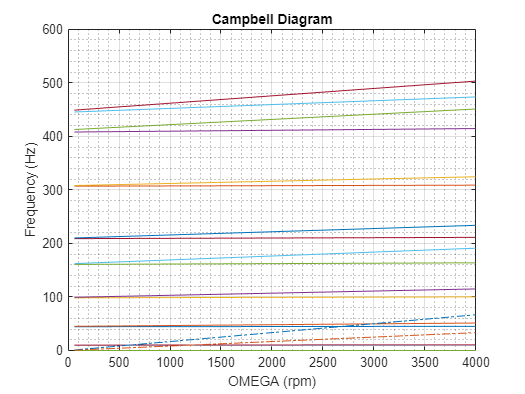


i = 1;
clear w F F_unsorted
for omega = [60,4000]
% for omega = [60, 100, 200, 500, 800, 1000, 2500, 3000, 4000]  % in rpm

    [kxx(1) ,kxz(1) ,kzx(1) ,kzz(1) ,cxx(1) ,cxz(1) ,czx(1) ,czz(1)]= turb(omega);
    [kxx(2) ,kxz(2) ,kzx(2) ,kzz(2) ,cxx(2) ,cxz(2) ,czx(2) ,czz(2)]= comp(omega);
    [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K);
    omega = omega*2*pi/60;
    [A,B] = matrix(M,C_new,K_new,n);
    A_num = vpa(A,2);
    B_num = vpa(B,2);
    A_num_new = subs(A_num,'omega',omega);
    [V_new,D_new]=eig(lsqminnorm(double(A_num_new),double(B_num)));

    [w_sorted,ind] = sort(imag(diag(D_new)),'ascend');
    F_unsorted(:,i) = imag(diag(D_new))./(2*pi);
    w(:,i) = w_sorted;
    i = i+1;
    F = w./(2*pi);
    if omega == 60*2*pi/60
        V_new_sorted = V_new(:,ind);
    else
        V_new_sorted2 = V_new(:,ind);
    end
end
omega = [60,4000];
% omega= [60, 100, 200, 500, 800, 1000, 2500, 3000, 4000];
plot(omega,F(n*4:n*4+20,:))        % Colision With y-axis (F) verified using (F0 = nat_freq/2pi)
grid on
grid minor
hold on
plot(omega,omega/60, '-.')
plot(omega,0.5*omega/60, '-.')
title('Campbell Diagram')
xlabel('OMEGA (rpm)')
ylabel('Frequency (Hz)')
hold off

F(n*4:n*4+20,:)

ans =          0         0
         0         0
         0         0
         0         0
         0         0
    9.8245    9.8796
   10.0332   10.5744
   44.3617   45.0776
   45.0918   51.2707
   98.3225  100.1670



syms x
y1(x) = x/60;
num = 1;
for i = n*4:n*8
    y2(x) = ((F(i,2)-F(i,1))/(4000-60))*(x - 60) + F(i,1);
    if vpasolve(y1 == y2) ~= 0
        crit_speed(num) = vpasolve(y1 == y2);
    end
    num = num+1;
end
crit_speed'

syms x
y1(x) = 0.5*x/60;
num = 1;
for i = n*4:n*8
    y2(x) = ((F(i,2)-F(i,1))/(4000-60))*(x - 60) + F(i,1);
    if vpasolve(y1 == y2) ~= 0
        crit_speed_half(num) = vpasolve(y1 == y2);
    end
    num = num+1;
end
crit_speed_half'

function [K11_fit_t ,K12_fit_t ,K21_fit_t ,K22_fit_t ,D11_fit_t ,D12_fit_t ,D21_fit_t ,D22_fit_t] = turb(speed_in)
method = 'cubicinterp';
speed_t = [367.8893038, 594.9139299, 964.0472719, 1495.62474, 2253.969678, 3272.634911, 6452.897062, 10064.89605, 14548.34974, 54432.60107];
K11_t = [1.96E+09, 1.31E+09, 9.07E+08, 7.03E+08, 5.52E+08, 4.67E+08, 4.23E+08, 4.75E+08, 5.55E+08, 1.24E+09];
K12_t = [2.69E+09, 1.69E+09, 1.08E+09, 6.90E+08, 3.55E+08, 1.98E+08, -2.94E+08, -8.76E+08, -1.59E+09, -6.98E+09];
K21_t = [7.65E+09, 5.18E+09, 3.64E+09, 2.83E+09, 2.26E+09, 1.95E+09, 1.74E+09, 1.75E+09, 2.03E+09, 5.57E+09];
K22_t = [2.42E+10, 1.54E+10, 1.04E+10, 7.46E+09, 5.43E+09, 4.52E+09, 3.75E+09, 4.13E+09, 5.16E+09, 1.69E+10];
D11_t = [1.12E+07, 4.66E+06, 2.23E+06, 1.55E+06, 1.11E+06, 8.13E+05, 7.18E+05, 6.98E+05, 6.89E+05, 5.73E+05];
D12_t = [2.89E+07, 9.77E+06, 3.49E+06, 2.07E+06, 1.01E+06, 2.62E+05, -3.17E+05, -6.29E+05, -8.34E+05, -1.03E+06];
D21_t = [2.80E+07, 9.30E+06, 3.27E+06, 2.03E+06, 1.08E+06, 2.93E+05, -3.19E+05, -6.32E+05, -8.38E+05, -1.04E+06];
D22_t = [2.51E+08, 1.08E+08, 4.91E+07, 2.75E+07, 1.65E+07, 1.02E+07, 5.80E+06, 4.69E+06, 4.47E+06, 4.26E+06];
K11_fit_t = fit(speed_t',K11_t',method);
K12_fit_t = fit(speed_t',K12_t',method);
K21_fit_t = fit(speed_t',K21_t',method);
K22_fit_t = fit(speed_t',K22_t',method);
D11_fit_t = fit(speed_t',D11_t',method);
D12_fit_t = fit(speed_t',D12_t',method);
D21_fit_t = fit(speed_t',D21_t',method);
D22_fit_t = fit(speed_t',D22_t',method);
if speed_in < speed_t(1)
    K11_fit_t = K11_t(1);
    K12_fit_t = K12_t(1);
    K21_fit_t = K21_t(1);
    K22_fit_t = K22_t(1);
    D11_fit_t = D11_t(1);
    D12_fit_t = D12_t(1);
    D21_fit_t = D21_t(1);
    D22_fit_t = D22_t(1);
elseif speed_in > speed_t(end)
    K11_fit_t = K11_t(end);
    K12_fit_t = K12_t(end);
    K21_fit_t = K21_t(end);
    K22_fit_t = K22_t(end);
    D11_fit_t = D11_t(end);
    D12_fit_t = D12_t(end);
    D21_fit_t = D21_t(end);
    D22_fit_t = D22_t(end);
else
    K11_fit_t = K11_fit_t(speed_in);
    K12_fit_t = K12_fit_t(speed_in);
    K21_fit_t = K21_fit_t(speed_in);
    K22_fit_t = K22_fit_t(speed_in);
    D11_fit_t = D11_fit_t(speed_in);
    D12_fit_t = D12_fit_t(speed_in);
    D21_fit_t = D21_fit_t(speed_in);
    D22_fit_t = D22_fit_t(speed_in);
end
end
function [K11_fit_c ,K12_fit_c ,K21_fit_c ,K22_fit_c ,D11_fit_c ,D12_fit_c ,D21_fit_c ,D22_fit_c] = comp(speed_in)
method = 'cubicinterp';
speed_c = [387.2429791, 626.2107655, 1014.763228, 1574.305569, 2372.545013, 3444.799508, 6792.366771, 10594.38339, 15313.69963, 57296.15507];
K11_c = [1.86E+09, 1.24E+09, 8.60E+08, 6.66E+08, 5.23E+08, 4.42E+08, 4.01E+08, 4.50E+08, 5.26E+08, 1.18E+09];
K12_c = [2.55E+09, 1.60E+09, 1.03E+09, 6.54E+08, 3.36E+08, 1.88E+08, -2.78E+08, -8.30E+08, -1.51E+09, -6.61E+09];
K21_c = [7.25E+09, 4.90E+09, 3.45E+09, 2.68E+09, 2.14E+09, 1.85E+09, 1.65E+09, 1.66E+09, 1.92E+09, 5.27E+09];
K22_c = [2.29E+10, 1.46E+10, 9.85E+09, 7.07E+09, 5.15E+09, 4.28E+09, 3.55E+09, 3.91E+09, 4.88E+09, 1.61E+10];
D11_c = [1.01E+07, 4.19E+06, 2.00E+06, 1.39E+06, 1.00E+06, 7.31E+05, 6.46E+05, 6.28E+05, 6.20E+05, 5.15E+05];
D12_c = [2.61E+07, 8.79E+06, 3.14E+06, 1.86E+06, 9.12E+05, 2.36E+05, -2.86E+05, -5.66E+05, -7.51E+05, -9.29E+05];
D21_c = [2.52E+07, 8.37E+06, 2.94E+06, 1.83E+06, 9.71E+05, 2.64E+05, -2.87E+05, -5.69E+05, -7.54E+05, -9.32E+05];
D22_c = [2.26E+08, 9.69E+07, 4.42E+07, 2.47E+07, 1.48E+07, 9.22E+06, 5.22E+06, 4.22E+06, 4.02E+06, 3.83E+06];
K11_fit_c = fit(speed_c',K11_c',method);
K12_fit_c = fit(speed_c',K12_c',method);
K21_fit_c = fit(speed_c',K21_c',method);
K22_fit_c = fit(speed_c',K22_c',method);
D11_fit_c = fit(speed_c',D11_c',method);
D12_fit_c = fit(speed_c',D12_c',method);
D21_fit_c = fit(speed_c',D21_c',method);
D22_fit_c = fit(speed_c',D22_c',method);
if speed_in < speed_c(1)
    K11_fit_c = K11_c(1);
    K12_fit_c = K12_c(1);
    K21_fit_c = K21_c(1);
    K22_fit_c = K22_c(1);
    D11_fit_c = D11_c(1);
    D12_fit_c = D12_c(1);
    D21_fit_c = D21_c(1);
    D22_fit_c = D22_c(1);
elseif speed_in > speed_c(end)
    K11_fit_c = K11_c(end);
    K12_fit_c = K12_c(end);
    K21_fit_c = K21_c(end);
    K22_fit_c = K22_c(end);
    D11_fit_c = D11_c(end);
    D12_fit_c = D12_c(end);
    D21_fit_c = D21_c(end);
    D22_fit_c = D22_c(end);
else
    K11_fit_c = K11_fit_c(speed_in);
    K12_fit_c = K12_fit_c(speed_in);
    K21_fit_c = K21_fit_c(speed_in);
    K22_fit_c = K22_fit_c(speed_in);
    D11_fit_c = D11_fit_c(speed_in);
    D12_fit_c = D12_fit_c(speed_in);
    D21_fit_c = D21_fit_c(speed_in);
    D22_fit_c = D22_fit_c(speed_in);
end
end
function [C_new, K_new] = bearings(kxx ,kxz ,kzx ,kzz ,cxx ,cxz ,czx ,czz ,n ,C, K)
C_new = C;
K_new = K;
n_bearings = [1 n];
size_n_bear = size(n_bearings);
for bearing = n_bearings
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        K_bearing =-[kxx(size_n_bear(1))  kxz(size_n_bear(1)) 0 0;
            kzx(size_n_bear(1))  kzz(size_n_bear(1)) 0 0;
            0   0 0   0;
            0   0 0   0];
    else
        K_bearing =-[kxx(size_n_bear(2))  kxz(size_n_bear(2)) 0 0;
            kzx(size_n_bear(2))  kzz(size_n_bear(2)) 0 0;
            0   0 0   0;
            0   0 0   0];
    end
    for i = 0:3
        for j = 0:3
            K_new(1+k*4+i,1+k*4+j)= K(1+k*4+i,1+k*4+j) + K_bearing(1+i,1+j);
        end
    end
    %     end
    k = bearing - 1;
    %     if 1+k*4 < n*4
    if k ~= n - 1
        C_bearing =-[cxx(size_n_bear(1))  cxz(size_n_bear(1)) 0 0;
            czx(size_n_bear(1))  czz(size_n_bear(1)) 0 0;
            0   0 0   0;
            0   0 0   0];
    else
        C_bearing =-[cxx(size_n_bear(2))  cxz(size_n_bear(2)) 0 0;
            czx(size_n_bear(2))  czz(size_n_bear(2)) 0 0;
            0   0 0   0;
            0   0 0   0];
    end

    for i = 0:3
        for j = 0:3
            C_new(1+k*4+i,1+k*4+j)= C(1+k*4+i,1+k*4+j) + C_bearing(1+i,1+j);
        end
    end
    %     end
end
end
function [A,B] = matrix(M,C,K,n)
A = [zeros(n*4)  M;M  C];
B = [M  zeros(n*4);zeros(n*4)  -K];
end